
% Script that creates a mp4 file of a series of sinusoid stimuli that can
% accelerate or decelerate and sound frequency also changes over the
% sequence
%
% created by Max Di Luca m.diluca@bham.ac.uk
% 25/11/2021


% 101*(1/30)= 3.3667

fs=48000;

total_required_samples = 166912;
total_required_length = total_required_samples/fs;
L=1/30;
A=1;
f=2000;
R=.005;
initial_silence=1.00;
initial_silence_samples = initial_silence*fs;
L_samples = L*fs;
final_silence_samples = total_required_samples - initial_silence_samples - L_samples;
final_silence = final_silence_samples/fs;

ISI=.1;
N=1;%number of sounds
df= 0; %change of the frequency at every stimulus
D=0.0; %change of ISI at every interval



t_singlestimulus= 0:1/fs:L;
t_singlestimulus = t_singlestimulus(1:end-1);
modulation=ones(size(t_singlestimulus));


length_smoothing=floor(R*fs);
length_smoothing=min(length_smoothing,length(t_singlestimulus)/2);
if length_smoothing>0
    modulation(1:length_smoothing+1)=0:1/length_smoothing:1;%-cos((0:1/lenght_smoothing:1)*pi)/2+.5;
    modulation(end:-1:end-length_smoothing)=0:1/length_smoothing:1;%-cos((0:1/lenght_smoothing:1)*pi)/2+.5;%0:1/lenght_smoothing:1;

end
% sound(sinusoid,fs)
% plot(t_singlestimulus,sinusoid)

number_of_D_in_the_sequence=sum((1:N-1)-1);
L_total=initial_silence+final_silence+L;




t_sequence=0:1/fs:L_total;
t_sequence = t_sequence(1:end-1);
trial=zeros(size(t_sequence));

sound_n=1

sound_n = 1



    sinusoid=A*modulation.*sind(t_singlestimulus*(f+df*(sound_n-1))*360);
    start_time_of_sound=initial_silence+ISI*(sound_n-1)+D*sum(max(1:sound_n-2,0));
    trial( floor(start_time_of_sound*fs):floor(start_time_of_sound*fs)+length(sinusoid)-1 )=sinusoid;


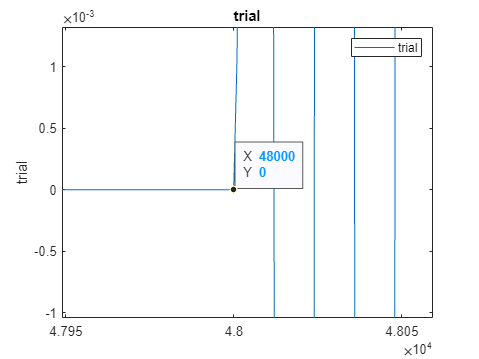

% Create plot of trial
h2 = plot(trial,"DisplayName","trial");

% Add ylabel, title, and legend
ylabel("trial")
title("trial")
legend

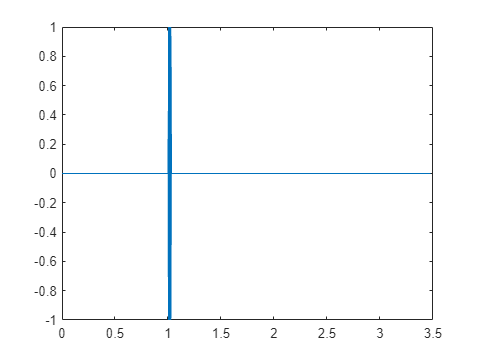


plot(t_sequence,trial)



sound(trial,fs)


filename = ['audio_beep.wav'];

audiowrite(filename,repmat(trial,[2,1])',fs, "BitsPerSample", 32);
